# **How To Cook Your Results (without even knowing it).**

Mohammad M. Ghassemi [1], Tuka Alhanai [2] 

December 19th, 2017

[1] [http://ghassemi.xyz,](http://ghassemi.xyz,) [2] [http://talhanai.com](http://talhanai.com)

## **Introduction: who has time for n-fold validation?**

With the rise in popularity of Deep Neural Networks (DNNs), statistical modeling requires greater computational resources than ever before. More computational power provides faster optimization of model hyper-parameters, which in turn provides better results, higher impact publications, media attention, and perhaps even startup fortunes. 

Even with the greatest of resources, advanced models can take a long time to train (hours to weeks, depending on the data). But in our phenomenally competitive research ecosystem, even short amounts time can make a difference between being scooped by a competitor, or being published in a premier journal/conference. 

In the persuit of better and faster results, many of us have relaxed our model validation standards. We all know and respect leave-one-out-cross validation (LOOCV) as a scientific ideal, but who has time for the weeks (or months) of computation it takes when the NIPS/AAAI/KDD deadline is looming? Indeed, there is little incentive (and perhaps even a penalty) for being rigourous in our work. Cross validation allows us to estiamte the variance in our model's performance but if that variance is too high, it might place our results in a less-flattering light compared to the literature baselines we have to beat if we want to publish. 

Instead of cross validating, many of us simply report our performance on a single training/vaidation/testing fold of the data (e.g. 70% training, 15% validation, 15% testing). At the surface, the approach seems fair: We train our models on the training set, we make sure it generalizes well by evaluating it on the validation set, and then (at the very end) we report our performance on the unseen testing set.

In reality however, we only report our performance on the testing set, *if the results were favorable*! When the results are not favorable (as they so often are), we start looking for another model (or setting of our existing model's hyper-parameters) that we think will do better. We then re-evaluate the new model on the "unseen" test set. This process is often repeated until we converge to a model with test-set performance that beats the baselines. 

This process is highly problematic because it leaks information from the testing set to the model, via the investigator. With each iteration, the investigator gets better at choosing the model, features, (or settings of the hyper-paramters) that optimize the performance of the method on the "unseen" test-set! This leakage of information from the testing to the training set is real, and all of us are guilty of it to a greater or lesser extent. This is one of the reasons it's important to have a healthy skepticism of models (both our own, and those of our peers) that are validated using a single trainin/validation/testing fold. For the rest of this article, I'll demonstrate how easilly we can cook our results, without even knowing it!

**tl;dr: Model validation can be a thankless task that consumes precious time, but it's also one of the most important parts of science.**

## The Data

To demonstrate the perils of single-fold research, we'll work on a simple binary prediction task using a small smoking data-set (100 rows of data). We'll use this data-set because it's small enough that we will be able to cross-validate things in a reasonable amount of time. First, let's load the data:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all;                                       % clear everything from our environment
load smoking.mat;                                % load the smoking data set
t = dataset2table(smoking);                      % convert it to 'table' format
t.Outcome = t.Smoker > 0;                        % generate an outcome variable
t.Smoker = [];                                   % remove the 'Smoker' field      
display(t)                                       % display the table

t = 100×6 table
    Sex    Age    Weight    SystolicBP    DiastolicBP    Outcome
    ___    ___    ______    __________    ___________    _______

    0      38     176       124           93             true   
    0      43     163       109           77             true   
    1      38     131       125           83             false  
    1      40     133       117           75             false  
    1      49     119       122           80             false  
    1      46     142       121           70             false  
    1      33     142       130           88             true   
    0      40     180       115           82             true   
    0      28     183       115           78             false  
    1      31     132       118           86             false  

The table contains information on the sex, age, weight and blood pressure (systolic and diastolic) of an 100 indivduals. 39 of those individuals are smokers, and 61 of them are non-smokers. 

## Predicting Smokers Using Logistic Regression (using all the data)

The goal of machine learning is to use one or more things we can observe in our data, to predict something else in our data. In this case we would like to predict the probability that a person is a smoker, based on their sex, age, weight and blood pressure. One simple model that does this mapping is logistic regression. Let's try training a logsitic regression model for our data:

formula = 'Outcome ~ 1 + DiastolicBP + Sex + Age + Weight + SystolicBP';    % the formula
model = fitglm(t,formula,'distr','binomial');                               % trains a logistic regression model

Now that the model is fit, we can use it to predict who in the data was a smoker, and who was not: 

predictions = predict(model,t);                                             % Predict the probability 

To assess the performance of our model, we will use the Area Under the Reciever Operator Curve (AUC). AUC is a useful metric for binary classification problems becasue it automatically accounts for potential differences in misclassfication costs (e.g. classifying a smoker as a non-smoker may not be as bad as classifying a non-smoker as a smoker). 

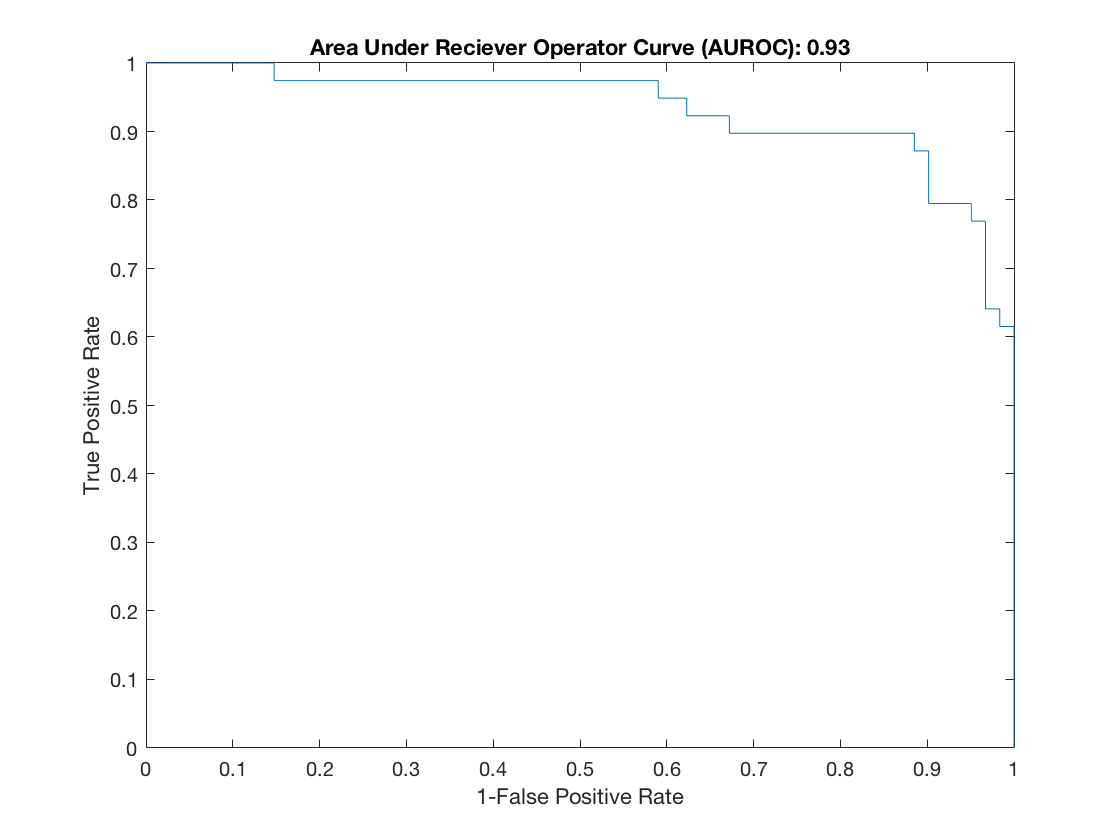

[X,Y,T,AUC,OPTROCPT] = perfcurve(t.Outcome,predictions,1);                  % Area Under Reciever Operator Curve
figure;plot(1-X,Y);                                                         % Plot the curve                                    
title(['Area Under Reciever Operator Curve (AUROC): ' num2str(round(AUC*100)/100)])
ylabel('True Positive Rate'); xlabel('1-False Positive Rate');

Our logistic regression model  yields an AUC of 0.93 (perfect performance is 1.0). That's great performance, but of course, any skeptical machine learning user would know not to trust this performance level because we tested the algorithm on the same data that we used to train the model! So, there is a good possibility that we *overfit*!

## Predict Smokers Using Logistic Regression (using one fold validation)

**Train the Models: **Now that we know what an overfit model looks like, let's get to the standard validation prcedure of many papers. We will partition our data into training and testing sets. We will identify model parameters using the training data (70%), and then evaluate the performance of the model using the held out test set (30%). Anyone that has worked on machine learning problems before knows that the precise properties of the training and testing data sets can have dramatic implications for the kind of performance we will see. To illustrate this, let's split the data 100 times, using different random seeds, each time. 

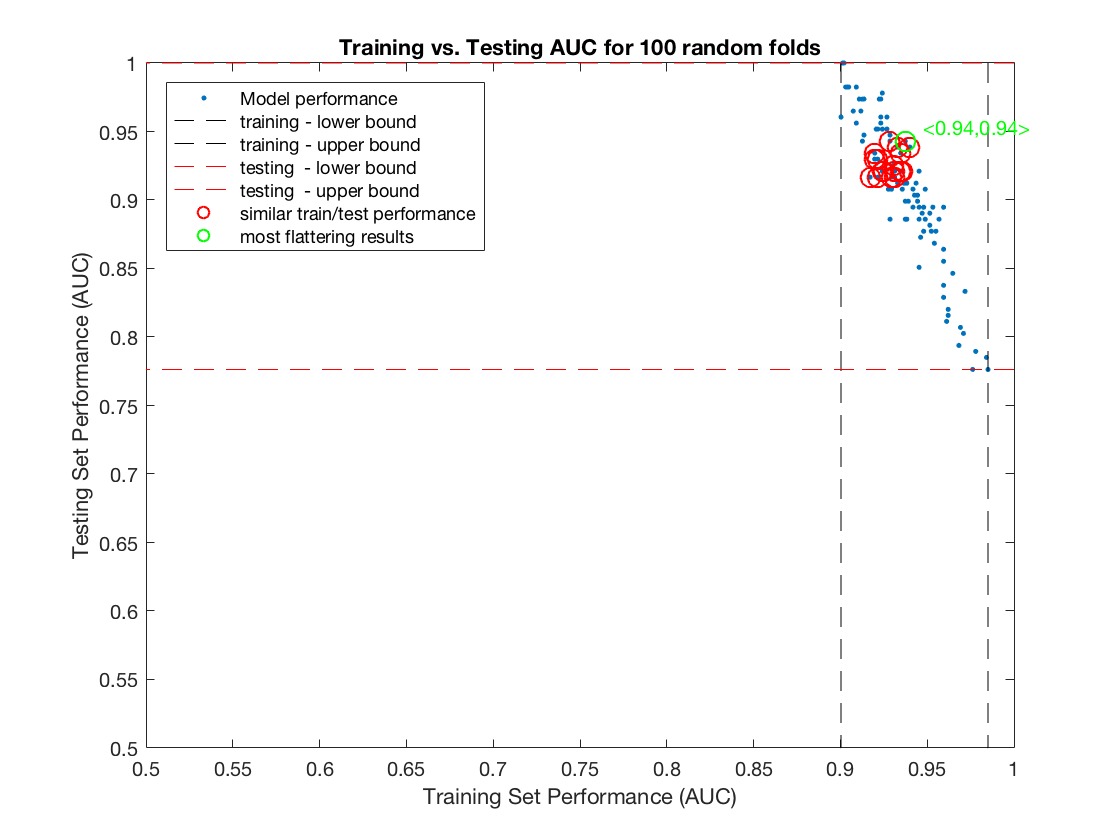

number_of_random_seeds = 100;
[train_AUC,test_AUC,odds_ratios] = use_logistic_regression(t,formula);
    figure; plot_results(train_AUC,test_AUC,number_of_random_seeds);

**Interpretation of Results: **In the above figure, we see huge fluctations in the performance of the model as a function of the way the data was split. The red dashed lines provide the range of performance on the testing set, while the black dashed lines outline the range in performance on the training set. The red circles indicates folds where the training and testing set performance are simmilar (AUC difference is less than 0.01), and the point circled in green is the fold that provides the most flattering results (the kind of thing we would want to report in a journal!).

The red circled points are worth highlighting because machine learning models are supposed to generalize what was observed in the training set to the testing set. Hence, there should not be large differences in model performance between the two sets, or it's an obvious sign that something went wrong.

But as the above figure shows, even if the training and testing set performances are simmilar, it provides no gaurantee that the results are robust. They may simply be the result of a lucky training-testing split. Even if we only consider the splits where the training and testing performance are *the same*, we may still see fluctuations in the AUC between 0.91 and 0.95. That gain in performance is non-trivial. Many papers are published on the basis of similar magnitudes of improved performance.

**tl;dr:** **Beware of models evaluated using a single fold! Performance levels can exceed even those of a model trained using *****all the data*****.**

**Model Coefficients: **If we are using a linear model, the coefficients of the model are interpretable. In the case of logistic regression, we can compute the odds-ratios, and visualize how they change across the random folds:

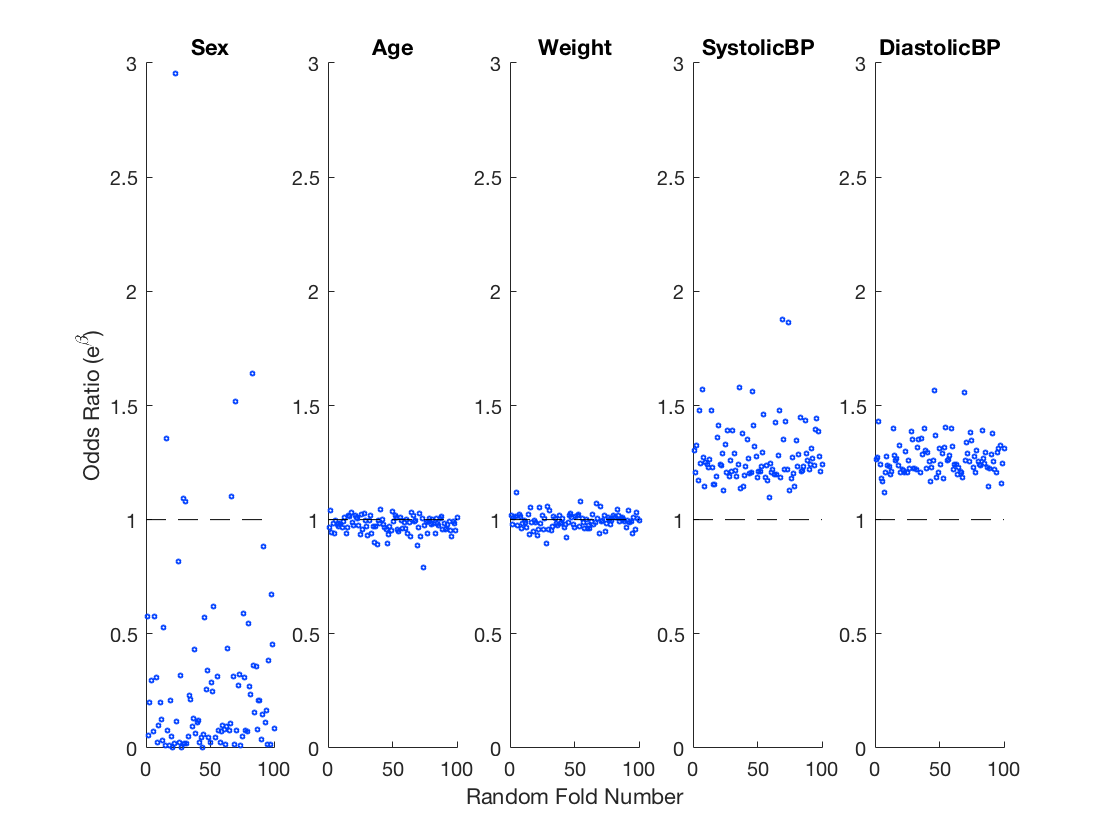

figure; plot_coefficients(t,number_of_random_seeds,odds_ratios,test_AUC)

In the above figure we see that the composition of our training/test sets can have drastic implications for how we *interpret* some of our model coefficients. The sex of the individual, for example, can range from having no predictive effect (close to 1), to being strongly associated with Males (close to 0), or associated with Females (greater than 1), all depending on how the data was sliced.

## Predict Smoking Using Neural Networks (one validation fold)

Everything we've seen so far has assumed we are using a logistic regression model, but what if we decide to use a more advanced method? These days, neural netwoks are all the rage. So, let's try them next. As before, let's split the data (70% training, 30% testing), and see how sensitive a 10x10 feedforward neural network is to the way that the data is split. As we did for the logistic regression, we'll balance the outcomes in the training and testing sets.

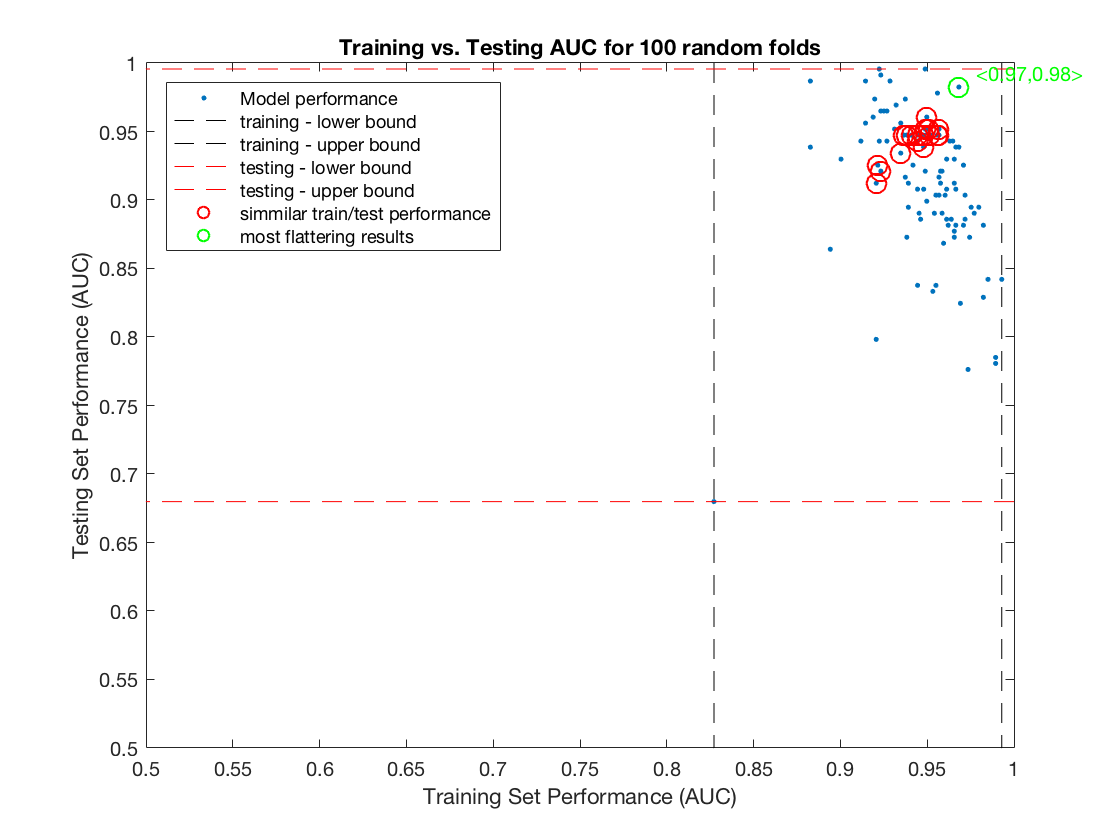

[train_AUC,test_AUC] = use_nn_random_fold(t);
figure; plot_results(train_AUC,test_AUC,number_of_random_seeds);                                                                               % set the y-axis range

Just as we observed for the logistic regression, there are huge variances in the performance of the models as a function of the training/ testing split. We can choose a training/test split that achieves up to 0.98 on the testing set even for the SAME initialization of the weights matrix!

**Effect of Weight Initialization: **By now, It should be painfully obvious that results can be easilly maniputed on single-fold studies by simply engineering the training and testing sets. Of course, most scientific investigators are not so nefarious that they would intentionally choose the training and testing folds this way. What is more common is for investigators to choose a given training and testing fold, and to then optimize their algorithm around it.

The problem is that investigators may train multiple models on the training set, and then (to determine which is best) choose the one with the best peformance on the testing set. This process, however, is problematic in the same way that engineering the training/testing split was. For any given split, we can also identify a random inital weight that creates bloated performance on the training/testing sets.

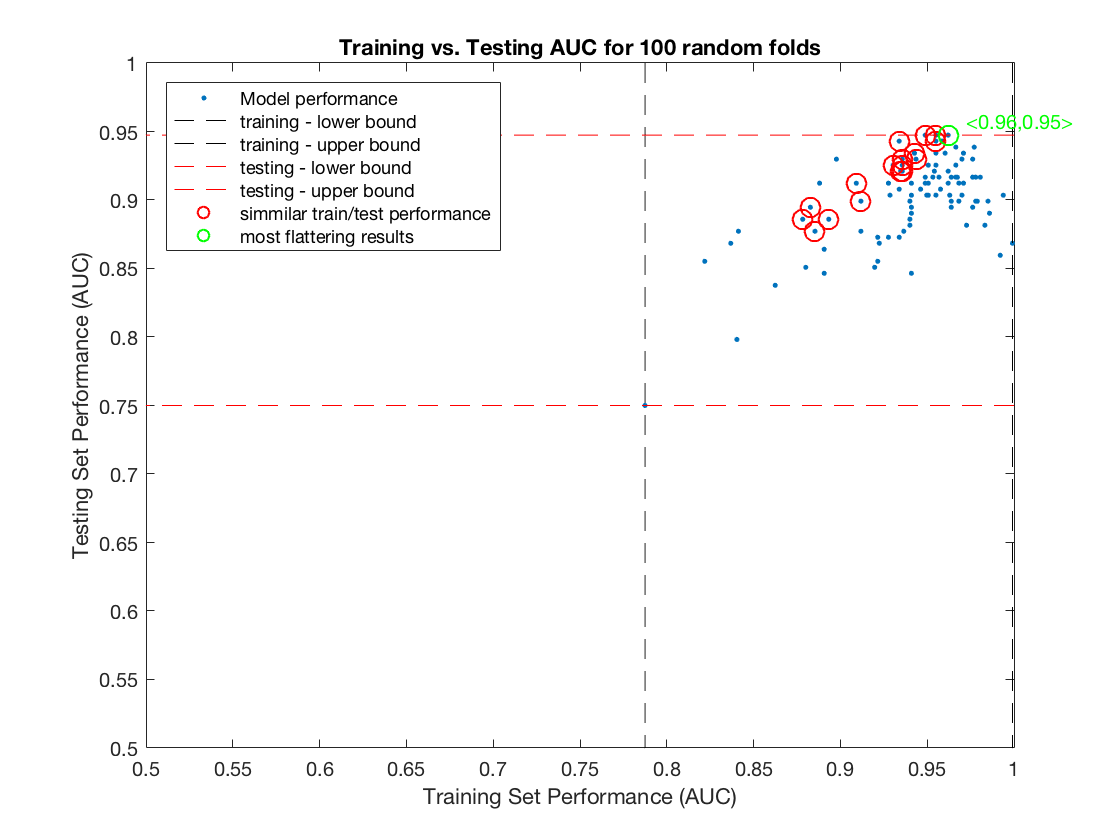

[train_AUC,test_AUC,weights] = use_nn_random_weights(t); 
plot_results(train_AUC,test_AUC,number_of_random_seeds);

Once again, we see large variance in the performance on the models as a function of the initial weights. This is itself not the problem, rather, the problem is that an investigator might be tempted to simply choose the initialization that gave the best performance* on testing set*.

**Plot the coefficients:**

I would opine on the effects of random initialization on the weights of the network, but they are not interpretable anyways:

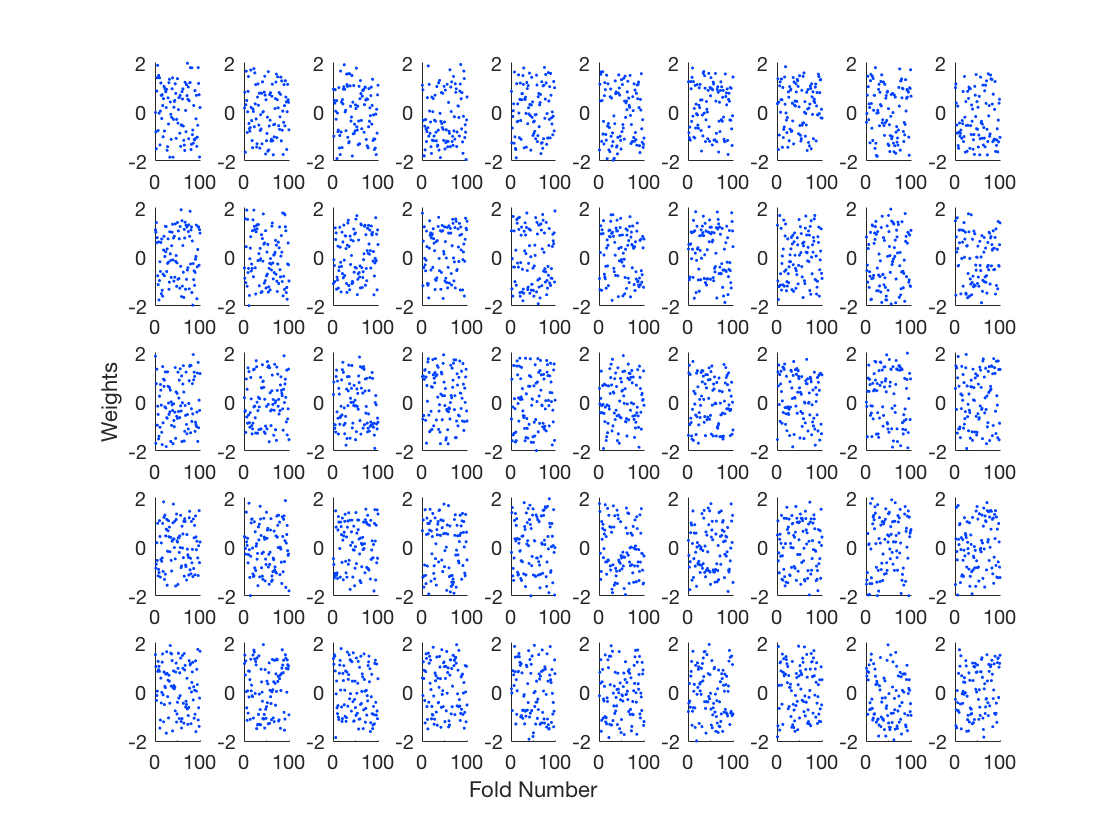

figure;plot_NN_coefficients(train_AUC,test_AUC,weights)

**Effects of Topology on performance: **So what if we choose a given fold, and given initialization of the network weights to stop the bias? Well, there is still the topology of the network that the investigator can tweak and (once again) that can lead to over-engineering the results: 

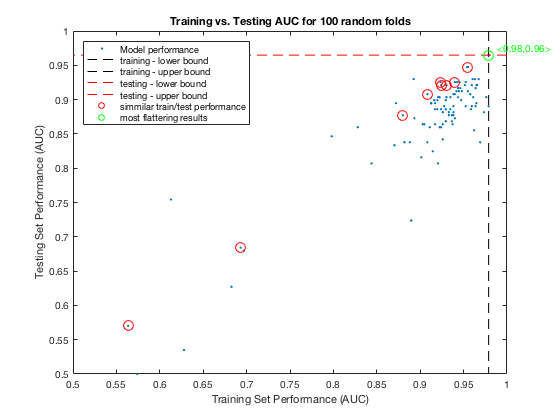

[train_AUC,test_AUC] = use_nn_random_topology(t);
plot_results(train_AUC,test_AUC,number_of_random_seeds) 

Here again, the variance in performance persits. We can get an AUC of 0.98 testing and 0.97 training by topology optimization.

## One Solution: Leave-One-Out-Cross-Validation (LOOCV)

The solution to this over-engineering is simple. Be rigourous, and use leave-one-out cross validation. Here's an example of how to do that with the logistic regression model:

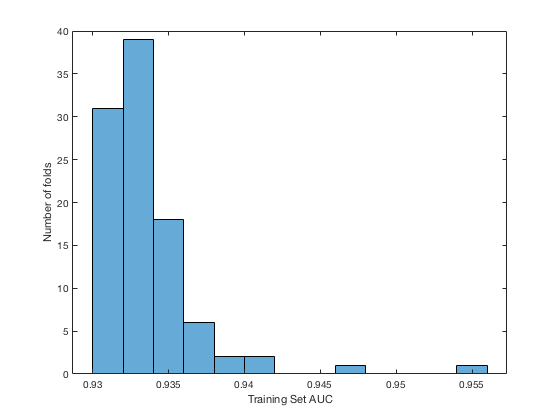

clear train_AUC test_AUC
for i = 1:height(t)
    tt = t;
    testing = tt(i,:); tt(i,:) = []; training = tt;
    model = fitglm(training,formula,'distr','binomial');
    
    %Evaluate performance of the training and testing sets.
    train_predictions = predict(model,training);
    test_predictions(i) = predict(model,testing);
    
    %Evaluate the AUC
    [~,~,~,train_AUC(i),~] = perfcurve(training.Outcome,train_predictions,1);
end

figure; histogram(train_AUC)                                        % Display a histogram of training set performance.
xlabel('Training Set AUC')
ylabel('Number of folds')

[~,~,~,test_AUC,~] = perfcurve(t.Outcome,test_predictions,1);       % Check the performance on the test set
display(['Test Set AUC: ' num2str(test_AUC)] )                      

Test Set AUC: 0.90248


Here, our performance is not as flattering, but it's also more believable because LOOCV does not allow us to get getting lucky with the training/testing fold split. The test AUC was 0.90. The mean AUC of the training models is 0.93 +/- 0.003

## Hacking LOOCV With Neural Networks:

But even with LOOCV, peaking at the testing set can still allows us to engineer our results. This is particularly relevant for Neural Networks because they have so many hyper-paramters we can modify. Let's try LOOCV after initializing the weights to 10 different values:

[train_AUC,test_AUC] = use_nn_random_weights_loocv(t);

1/

2/

3/

4/

5/

6/

7/

8/

9/

10/



display(['Best LOOCV Performance: ' num2str(max(test_AUC))])

Best LOOCV Performance: 0.91593


display(['Worst LOOCV Performance: ' num2str(min(test_AUC))])

Best LOOCV Performance: 0.86885


 Here we see that even the LOOCV testing set performance can be manipulated. It ranges from 0.86 to 0.92 - a huge difference! So, can we trust these results? Is is fair to choose the initialization of the weights that gave the most flattering performance? What is to be done?

## Conclusions:

Every time you look at the model's performance on the testing set, be aware that you are doing exactly what the code in this little script is doing. You may never train on the test sets directly, but your knowledge of the data can leak into the way you engineer the models to produce an over-engineered result that doesn't work in the real world. 

Never forget that science is, first and foremost, about finding the truth.